## Pipeline Part 7: Sensitivity analysis

overwritefiles = true;

args.p7.v.alpha = 0.0032;%10^(-3.6); %alpha which gives best yield at cellulose scale 1 with Lit Params
args.p7.v.km_cel = convertMgPerMlToMmolar(0.2,args.p2.v.glcpercellulose * args.p2.v.mass_glcmonomer); %0.0056

Reference to non-existent field 'p2'.

args.p7.v.kcat_cel = 32;

%Generate the data

args.p7.factors = [32 16 8 4 2 2^.5 2^-.5 1/2 1/4 1/8 1/16 1/32]; %1x is implicit

%Designate which params should be varied
args.p7.dims.alpha = 1;
args.p7.dims.alpha_initenz = 0;
args.p7.dims.initenz = 0;
args.p7.dims.kcat_cel = 1;
args.p7.dims.km_cel = 1;
args.p7.dims.vmax_glc = 1;
args.p7.dims.km_glc = 1;
args.p7.dims.decayrate = 1;
args.p7.dims.costfactor = 1;
args.p7.dims.atpperpeptide = 1;
args.p7.dims.gtpperpeptide = 1;
args.p7.dims.energyperpeptide = 1;
args.p7.dims.initman = 1;
args.p7.dims.ngam = 1;
args.p7.dims.gam = 1;
args.p7.dims.ngam_and_gam = 1;
args.p7.dims.initialpop = 1;

if ~exist('remcfg','var')
    load remoteconfig;
end

%7/14 rerun data that had erroneous values
args.p7.dims.alpha = 0;
args.p7.dims.alpha_initenz = 0;
args.p7.dims.initenz = 0;
args.p7.dims.kcat_cel = 0;
args.p7.dims.km_cel = 0;
args.p7.dims.vmax_glc = 0;
args.p7.dims.km_glc = 1;
args.p7.dims.decayrate = 0;
args.p7.dims.costfactor = 1;
args.p7.dims.atpperpeptide = 0;
args.p7.dims.gtpperpeptide = 0;
args.p7.dims.energyperpeptide = 0;
args.p7.dims.initman = 0;
args.p7.dims.ngam = 0;
args.p7.dims.gam = 1;
args.p7.dims.ngam_and_gam = 0;
args.p7.dims.initialpop = 0;
args.p7.v.timestep = 0.999;



if runPart7
    layouts7 = part7_generation_remote(args.p7);
    [layouts7,remcfg] = runCometsRemotely(layouts7,remcfg);
end


% %temp 7/14
% remcfg.batchnum = '200713180506';
% 
% for i = 1:length(layouts7)
%     layouts7{i}.params.biomassLogName = 'biomass.m';
%     layouts7{i}.params.mediaLogName = 'media.m';
% end

%load data
if runPart7
    clear dat7_full;
    dat7 = part7_parseRemoteResults(layouts7,remcfg.batchnum);
    layouts7 = dat7.layout;
    dat7.layout = cell(length(layouts7),1);
else
    load([datadir '/dat7.mat']);
end
dat7_backup = dat7;

%filter down to one experiment type
if ~exist('dat7_full','var')
    dat7_full = dat7;
end
dat7 = dat7_full;
enzInMaint = 0;
variableInitEnz = 0;
dat7 = dat7(dat7.enzyme_in_maint == enzInMaint,:);
dat7 = dat7(dat7.variable_init_enzyme == variableInitEnz,:);

% %build the data arrays
% d7.alpha = dat7(strcmp(dat7.permuted,'alpha')|strcmp(dat7.permuted,'none'),:);
% d7.atp = dat7(strcmp(dat7.permuted,'atp per peptide')|strcmp(dat7.permuted,'none'),:);
% d7.gtp = dat7(strcmp(dat7.permuted,'gtp per peptide')|strcmp(dat7.permuted,'none'),:);
% d7.energy = dat7(strcmp(dat7.permuted,'energy per peptide')|strcmp(dat7.permuted,'none'),:);
% d7.costfactor = dat7(strcmp(dat7.permuted,'costfactor')|strcmp(dat7.permuted,'none'),:);
% d7.decayrate = dat7(strcmp(dat7.permuted,'decayrate')|strcmp(dat7.permuted,'none'),:);
% d7.kcat_cel = dat7(strcmp(dat7.permuted,'kcat_cel')|strcmp(dat7.permuted,'none'),:);
% d7.km_cel = dat7(strcmp(dat7.permuted,'km_cel')|strcmp(dat7.permuted,'none'),:);
% d7.vmax_glc = dat7(strcmp(dat7.permuted,'vmax_glc')|strcmp(dat7.permuted,'none'),:);
% d7.km_glc = dat7(strcmp(dat7.permuted,'km_glc')|strcmp(dat7.permuted,'none'),:);

%Remove runs that didn't complete
filterIncompleteRows = false;
filterIncompleteRows = true;

if filterIncompleteRows
    [nrows,ncols] = size(dat7);
    relvel = zeros(nrows,1);
    for i = 1:nrows
        delta = dat7.biomass_delta{i} ./ max(dat7.biomass_delta{i});
        relvel(i) = delta(end);
    end
    finished = relvel < .01;
    nrows - sum(finished)
    incomplete = dat7(~finished,:);
    incomplete = sortrows(incomplete,'permuted');
    incomplete.petmutation_scale_log2 = log2(incomplete.permutation_scale);
    
    dat7 = dat7(finished,:);
end

ans = 0

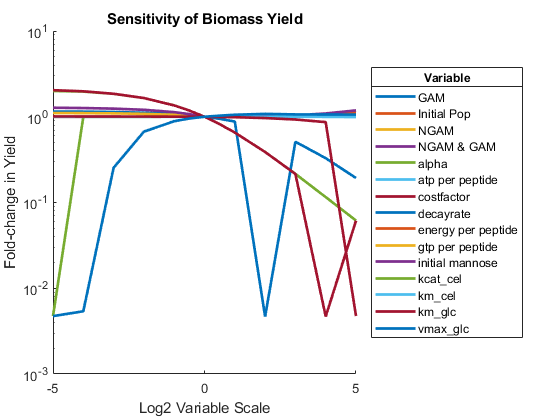

%plot sensitivity of yield
permfields = unique(dat7.permuted);
% permfields = {'km_cel'};
permfields = permfields(~strcmp(permfields,'none'));
% permfields = permfields(~strcmp(permfields,'atp per peptide'));
% permfields = permfields(~strcmp(permfields,'gtp per peptide'));
% 
% permfields = {'alpha' 'alpha plus initial enzyme' 'initial enzyme'};
% permfields = {'kcat_cel', 'km_cel', 'vmax_glc', 'km_glc'};
% permfields = {'costfactor', 'decayrate'};
% permfields = {'energy per peptide' 'atp per peptide' 'gtp per peptide'};

colors = lines(length(permfields));
baserow = dat7(strcmp(dat7.permuted,'none'),:);
figure();
hold on;
all_y = [];
for i = 1:length(permfields)
    f = permfields{i};
    rows = dat7(strcmp(dat7.permuted,f)|strcmp(dat7.permuted,'none'),:);
    rows = sortrows(rows,'permutation_scale');
    plot(log2(rows.permutation_scale),rows.biomass_max./baserow.biomass_max(1),'linewidth',2,'color',colors(i,:),'DisplayName',strrep(f,'_','\_'));
    all_y = vertcat(all_y,rows.biomass_max./baserow.biomass_max(1));
end
hold off;
leg = legend('location','eastoutside');
title(leg,'Variable');
set(gca,'yscale','log');
ylabel('Fold-change in Yield');
xlabel('Log2 Variable Scale');
ylim([.001,10]);
title('Sensitivity of Biomass Yield')

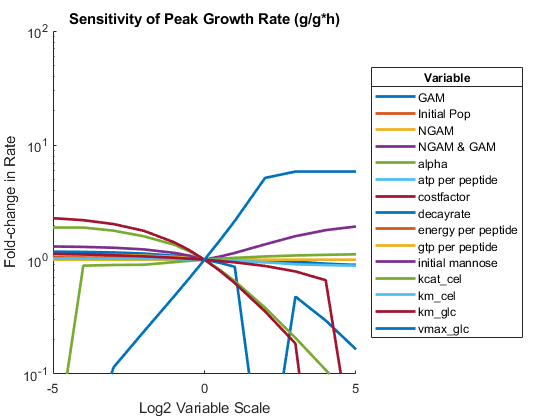

%plot sensitivity of peak growth rate

%populate rate columns
[nrows,ncols] = size(dat7);
for i = 1:nrows
    dat7.g_per_h{i} = dat7.biomass_delta{i} / dat7.t{i}(2);
    dat7.g_per_g_per_h{i} = dat7.g_per_h{i} ./ dat7.biomass{i}(1:end-1);
    dat7.maxrate(i) = max(dat7.g_per_g_per_h{i});
end

permfields = unique(dat7.permuted);
% permfields = {'km_cel'};
permfields = permfields(~strcmp(permfields,'none'));
% permfields = permfields(~strcmp(permfields,'atp per peptide'));
% permfields = permfields(~strcmp(permfields,'gtp per peptide'));

% 
% permfields = {'alpha' 'alpha plus initial enzyme' 'initial enzyme'};
% permfields = {'kcat_cel', 'km_cel', 'vmax_glc', 'km_glc'};
% permfields = {'costfactor', 'decayrate'};
% permfields = {'energy per peptide' 'atp per peptide' 'gtp per peptide'};

colors = lines(length(permfields));
baserow = dat7(strcmp(dat7.permuted,'none'),:);
figure();
hold on;
all_y = [];
for i = 1:length(permfields)
    f = permfields{i};
    rows = dat7(strcmp(dat7.permuted,f)|strcmp(dat7.permuted,'none'),:);
    rows = sortrows(rows,'permutation_scale');
    plot(log2(rows.permutation_scale),rows.maxrate./baserow.maxrate(1),'linewidth',2,'color',colors(i,:),'DisplayName',strrep(f,'_','\_'));
    all_y = vertcat(all_y,rows.maxrate./baserow.maxrate(1));
end
hold off;
leg = legend('location','eastoutside');
title(leg,'Variable');
set(gca,'yscale','log');
ylabel('Fold-change in Rate');
xlabel('Log2 Variable Scale');
ylim([.1,100]);
title('Sensitivity of Peak Growth Rate (g/g*h)');

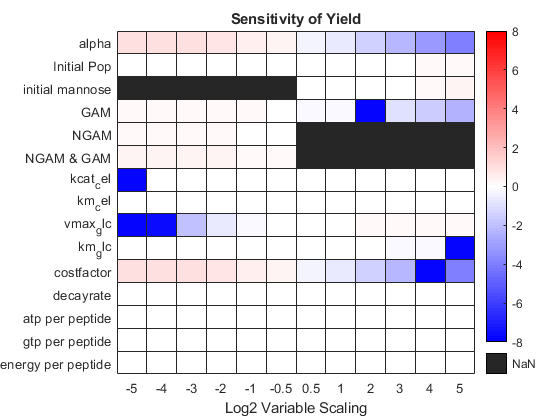

%Make a heat map of the data

% %method to reorder the y axis: use indexes instead of names
% permfields = unique(dat7.permuted);
% dat7.variableID = cellfun(@(x) stridx(x,permfields,false),dat7.permuted,'UniformOutput',false);
% dat7.variableID = cellfun(@(x) x,dat7.variableID);
% %yOrderArr = [12 1 2 8 3 7 6 9 10 11 13 4 5 14:30];
% 
% %Permfields order:
% % 4    {'GAM'               }
% % 2    {'Initial Pop'       }
% % 5    {'NGAM'              }
% % 6    {'NGAM & GAM'        }
% % 1    {'alpha'             }
% % 13    {'atp per peptide'   }
% % 11    {'costfactor'        }
% % 12    {'decayrate'         }
% % 15    {'energy per peptide'}
% % 14    {'gtp per peptide'   }
% % 3    {'initial mannose'   }
% % 7    {'kcat_cel'          }
% % 8    {'km_cel'            }
% % 10    {'km_glc'            }
% % 0    {'none'              }
% % 9    {'vmax_glc'          }
% yOrderArr = [4 2 5 6 1 13 11 12 14 15 3 7 8 10 0 9];
% 
% vidx = arrayfun(@(x) find(x == yOrderArr) - 1,dat7.variableID,'UniformOutput',false);
% dat7.variableIdx = cellfun(@(x) x(1),vidx);

permfields = {'none' 'alpha' 'Initial Pop' 'initial mannose' 'GAM' 'NGAM'...
    'NGAM & GAM' 'kcat_cel' 'km_cel' 'vmax_glc' 'km_glc'...
    'costfactor' 'decayrate' 'atp per peptide' 'gtp per peptide'...
    'energy per peptide'};
dat7.variableIdx = cellfun(@(x) stridx(x,permfields,false)-1 , dat7.permuted);

dat7.relative_yield = dat7.biomass_max ./ baserow.biomass_max(1);
dat7.relative_yield_log2 = log2(dat7.relative_yield);
dat7.relative_yield_log10 = log10(dat7.relative_yield);
dat7.scale_log2 = log2(dat7.permutation_scale);
cmap = horzcat([(0:.02:1)' ; ones(50,1)], [(0:.02:1)' ; (.98:-.02:0)'], [ones(50,1);(1:-.02:0)']);
maxval = ceil(max(abs(dat7.relative_yield_log2)));
h = heatmap(dat7(dat7.variableIdx > 0,:),'scale_log2','variableIdx','colorvar','relative_yield_log2','ColorScaling','scaled','colormap',cmap,'colorlimits',[-maxval maxval]);
h.YDisplayLabels = permfields(2:end);
title('Sensitivity of Yield');
xlabel('Log2 Variable Scaling');
ylabel('');

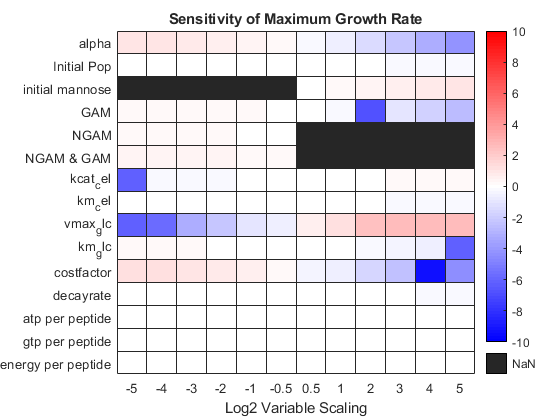


dat7.relative_maxrate = dat7.maxrate ./ baserow.maxrate(1);
dat7.relative_maxrate_log2 = log2(dat7.relative_maxrate);
maxratelog2 = dat7.relative_maxrate_log2;
maxratelog2(isinf(maxratelog2)) = NaN;
maxval = ceil(max(abs(maxratelog2)));
h = heatmap(dat7(dat7.variableIdx > 0,:),'scale_log2','variableIdx','colorvar','relative_maxrate_log2','ColorScaling','scaled','colormap',cmap,'colorlimits',[-maxval maxval]);
h.YDisplayLabels = permfields(2:end);
title('Sensitivity of Maximum Growth Rate');
xlabel('Log2 Variable Scaling');
ylabel('');


%TODO: Rebalance color scale so 10^0 is in the middle
%TODO find a way to oconvert this to log scale so the stff at the lower end
%doesn't all get smooshed together.

%Possible way to combine the two tables: "Radial heat map AKA Feature expression 
% heat map". Eeach cell contains a colored %circle. size for one outcome, color
% for the other. Example: https://www.evolytics.com/wp-content/uploads/Tableau-Heat-Map-Feature.jpg
% https://ars.els-cdn.com/content/image/1-s2.0-S1532046414002238-fx1.jpg

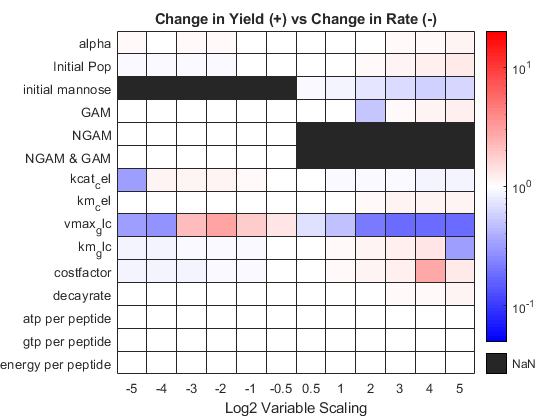

%look at the correlation of the two outcomes
perm = dat7.relative_yield ./ dat7.relative_maxrate;
for i = 1:length(perm)
    if perm(i) < 1
        perm(i) = -1/perm(i);
        perm(i) = perm(i) + 1;
    else
        perm(i) = perm(i) - 1;
    end
end
%perm = log2(perm);

%temp
perm = dat7.relative_yield ./ dat7.relative_maxrate;

%perm = log2(perm);
dat7.yieldperm_over_rateperm = perm;
maxval = max(ceil(abs(perm(~isinf(perm)))));
maxval = max(ceil(abs(log2(perm(~isinf(perm))))));
h = heatmap(dat7(dat7.variableIdx > 0,:),'scale_log2','variableIdx','colorvar','yieldperm_over_rateperm','ColorScaling','log','colormap',cmap,'colorlimits',[-maxval maxval]);
% yoa = yOrderArr(2:end);
% h.YDisplayLabels = permfields(yoa);
h.YDisplayLabels = permfields(2:end);
title('Change in Yield (+) vs Change in Rate (-)');
xlabel('Log2 Variable Scaling');
ylabel('');

%zlabel('Relative Effect');

%Create plots for each field individually
permfields = unique(dat7.permuted);
permfields = permfields(~strcmp(permfields,'none'));

permfields

permfields = 15×1 cell array
    {'GAM'               }
    {'Initial Pop'       }
    {'NGAM'              }
    {'NGAM & GAM'        }
    {'alpha'             }
    {'atp per peptide'   }
    {'costfactor'        }
    {'decayrate'         }
    {'energy per peptide'}
    {'gtp per peptide'   }
    {'initial mannose'   }
    {'kcat_cel'          }
    {'km_cel'            }
    {'km_glc'            }
    {'vmax_glc'          }


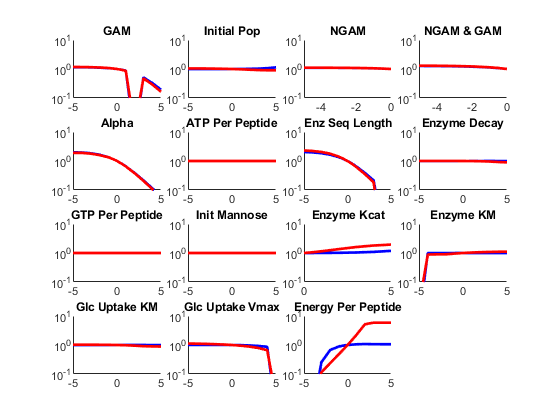


titles = {'GAM';               
    'Initial Pop';
    'NGAM';
    'NGAM & GAM';
    'Alpha';
    'ATP Per Peptide';
    'Enz Seq Length';
    'Enzyme Decay';
    'GTP Per Peptide';
    'Init Mannose';
    'Enzyme Kcat';
    'Enzyme KM';
    'Glc Uptake KM';
    'Glc Uptake Vmax';
    'Energy Per Peptide'};

baserow = dat7(strcmp(dat7.permuted,'none'),:);
fig = figure();
hold on;
for i = 1:length(permfields)
    f = permfields{i};
    name = titles{i};
    %figure('position',[0 0 200 200]);
    subplot(4,4,i);
    rows = dat7(strcmp(dat7.permuted,f)|strcmp(dat7.permuted,'none'),:);
    rows = sortrows(rows,'permutation_scale');
    hold on;
    plot(log2(rows.permutation_scale),rows.biomass_max./baserow.biomass_max(1),'linewidth',2,'color','b');
    plot(log2(rows.permutation_scale),rows.maxrate./baserow.maxrate(1),'linewidth',2,'color','r');
    title(strrep(name,'_','\_'));
    set(gca,'yscale','log');
    %ylabel('Fold-change');
    %xlabel('Log2 Variable Scale');
    ylim([.1,10]);
    %ylim([.001,10]);
    hold off;
end
%Red = rate, Blue = yield


if overwritefiles
    savefig(fig,'C:\sync\biomes\cellulose\optima\data_for_paper\figs\sensitivity','compact');
    saveas(fig,'C:\sync\biomes\cellulose\optima\data_for_paper\figs\sensitivity.png');
    saveas(fig,'C:\sync\biomes\cellulose\optima\data_for_paper\figs\sensitivity.eps');%for LaTeX
end

Individual Sensitivity Plots

name = 'GAM'

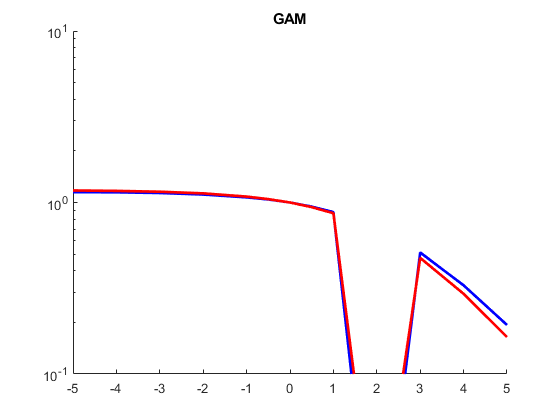

name = 'Initial Pop'

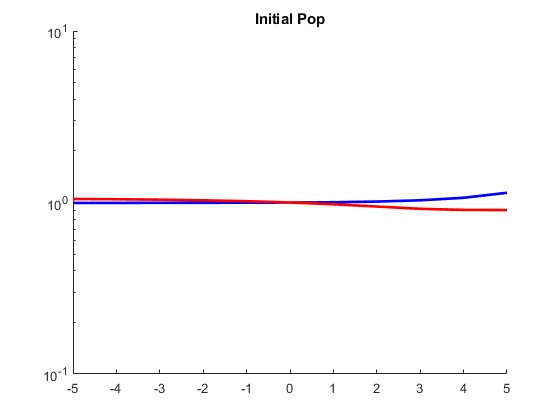

name = 'NGAM'

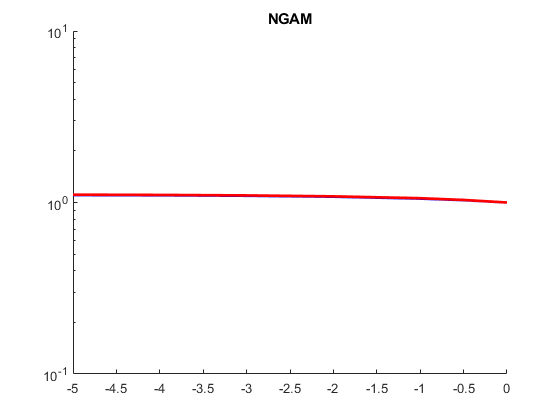

name = 'NGAM & GAM'

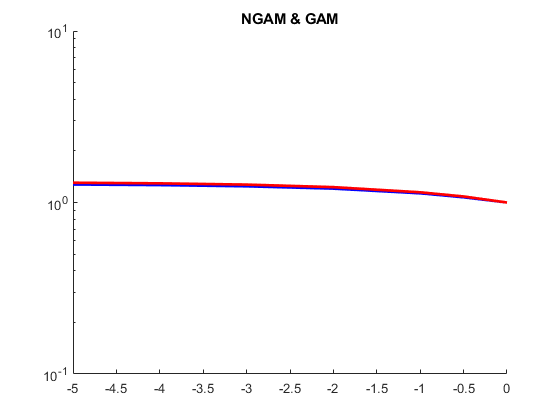

name = 'Alpha'

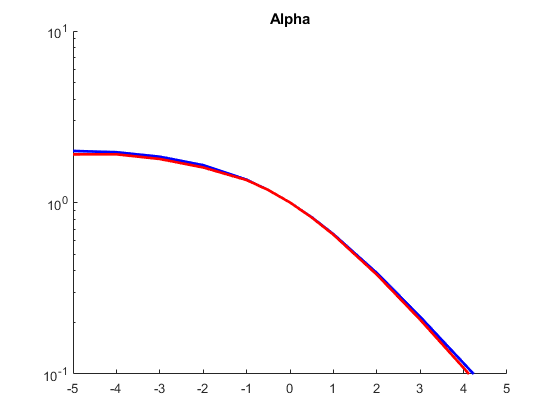

name = 'ATP Per Peptide'

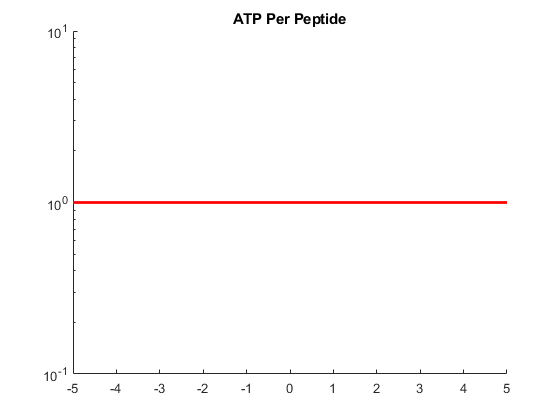

name = 'Enz Seq Length'

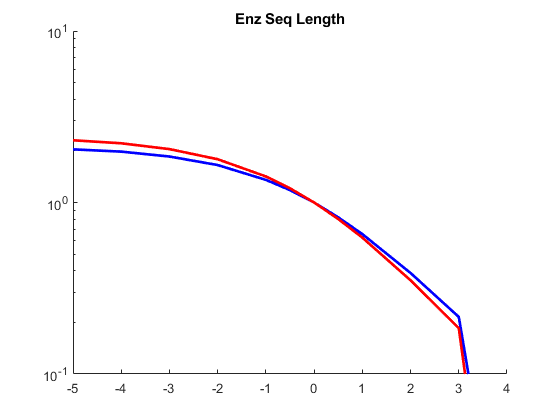

name = 'Enzyme Decay'

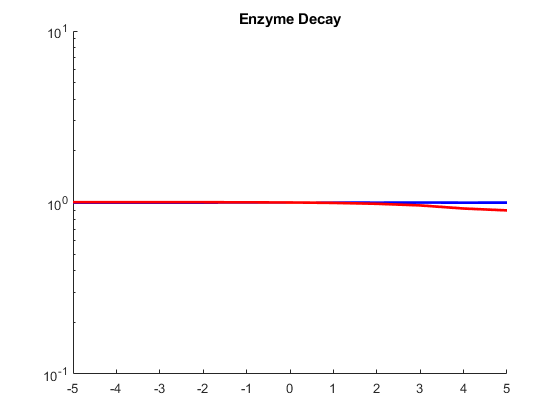

name = 'GTP Per Peptide'

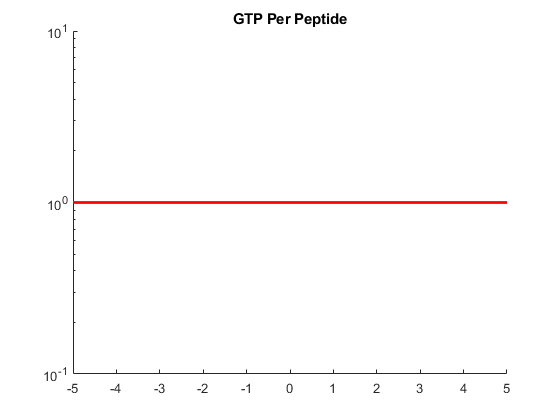

name = 'Init Mannose'

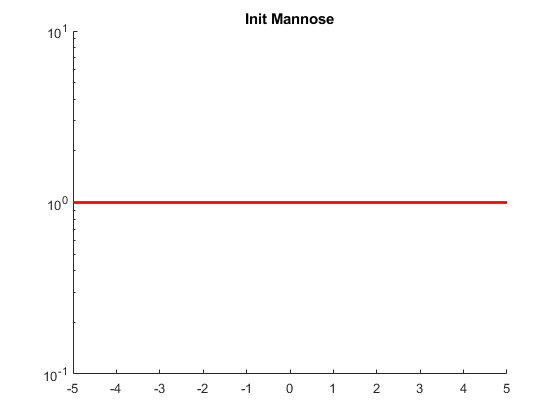

name = 'Enzyme Kcat'

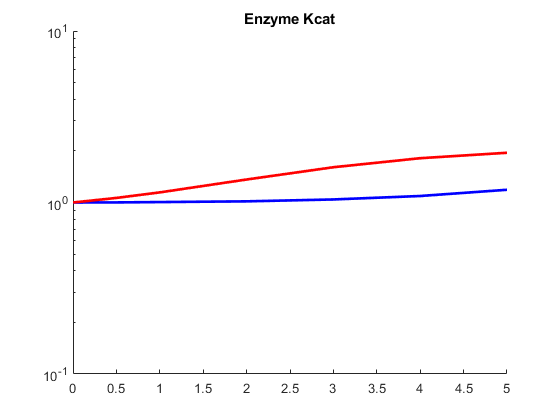

name = 'Enzyme KM'

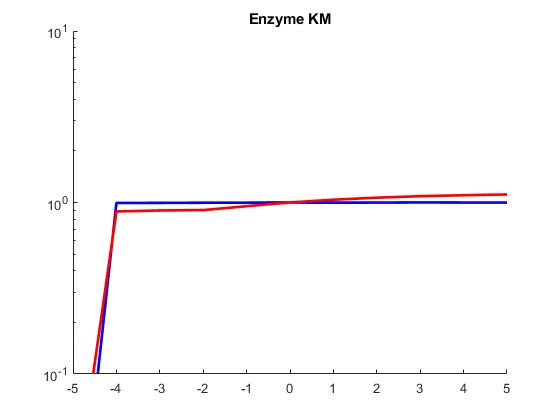

name = 'Glc Uptake KM'

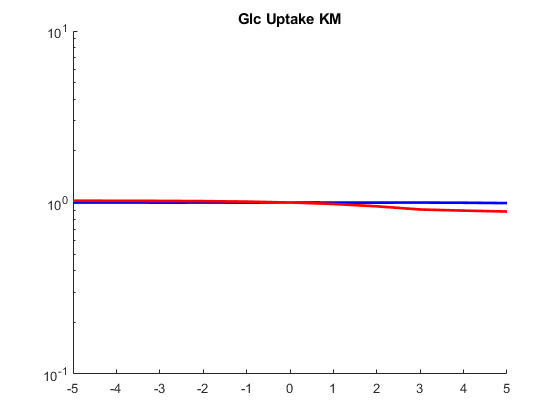

name = 'Glc Uptake Vmax'

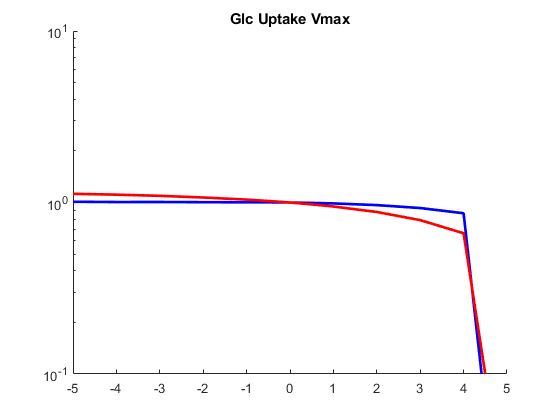

name = 'Energy Per Peptide'

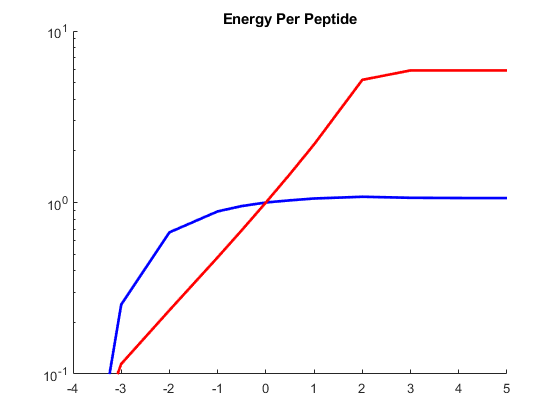

filepath = 'C:\sync\biomes\cellulose\optima\data_for_paper\figs\sensitivity\';


for i = 1:length(permfields)
    fig = figure();
    hold on;
    f = permfields{i};
    name = titles{i}
    %figure('position',[0 0 200 200]);
    rows = dat7(strcmp(dat7.permuted,f)|strcmp(dat7.permuted,'none'),:);
    rows = sortrows(rows,'permutation_scale');
    hold on;
    plot(log2(rows.permutation_scale),rows.biomass_max./baserow.biomass_max(1),'linewidth',2,'color','b');
    plot(log2(rows.permutation_scale),rows.maxrate./baserow.maxrate(1),'linewidth',2,'color','r');
    title(strrep(name,'_','\_'));
    set(gca,'yscale','log');
    %ylabel('Fold-change');
    %xlabel('Log2 Variable Scale');
    ylim([.1,10]);
    %ylim([.001,10]);
    hold off;
    
    if overwritefiles
    saveas(fig,[filepath name '.png']);
    end
end